# Predicting stage progression for chronic kidney disease (CKD)

Written by D.S.Jokhun on 12.02.2020

This is the main pipeline to analyse the medical timeseries data provided for the Holmusk data science task. It directly or indirectly requires the following custom functions to work:

model_LDA,

Regress_costFunctionReg, Regress_predict, Regress_sigmoid, RegressClassi,

NeuNet, NeuNet_fmincg, NeuNet_nnCostFunction, NeuNet_predict, NeuNet_randInitializeWeights, NeuNet_sigmoid and NeuNet_sigmoidGradient.

The data is imported from CSV files with filenames starting with 'T_'.

clear all  % Clearing the workspace

## Importing the raw data

% RawData is a structured array into which all the data provided (CSV files with filename starting with 'T_') are imported

RawData=[];
Filenames=dir('T_*.csv');
FieldNames=cell(length(Filenames),1);  % FieldNames will contain the name of the original parameters (e.g. Glucose, creatinine...)
for file_count=1:length(Filenames)
    Filename=Filenames(file_count).name;
    FieldNames{file_count}=string(extractBetween(Filename,'_','.'));
    RawData.(FieldNames{file_count})=struct([]);
    RawData.(FieldNames{file_count})=readtable(Filename); % importing the CSV files under their respective Fieldnames
end

% CompleteData_GrndTrth contains the stage progress status of all the patients in binary format
CompleteData_GrndTrth=table(categorical(RawData.stage.Stage_Progress)=='True','VariableNames',{'Class'});

% CompleteData will be built in stages. It is a table containing all the data of all the patients
CompleteData=RawData.demo(:,2:4);  % Adding race, gender and age
CompleteData.race=categorical(CompleteData.race);
CompleteData.gender=categorical(CompleteData.gender);


## Preprocessing timeseries data


TimeseriesFields=[1:4,6,7]; % Defining the continuous timeseries fields
id=RawData.demo{:,1};
Timeseries_ParamNames=cell(1,7*numel(TimeseriesFields)); % There will be 7 features extracted from each continuous timeseries field
Timeseries_Params=zeros(length(id),size(Timeseries_ParamNames,2));
Field_count=0;
for TimeseriesField_count=TimeseriesFields
    Field_count=Field_count+1;
    % Defining the feature titles
    Timeseries_ParamNames{(Field_count*7)-6}=[char(FieldNames{TimeseriesField_count}),'_min'];
    Timeseries_ParamNames{(Field_count*7)-5}=[char(FieldNames{TimeseriesField_count}),'_max'];
    Timeseries_ParamNames{(Field_count*7)-4}=[char(FieldNames{TimeseriesField_count}),'_mean'];
    Timeseries_ParamNames{(Field_count*7)-3}=[char(FieldNames{TimeseriesField_count}),'_med'];
    Timeseries_ParamNames{(Field_count*7)-2}=[char(FieldNames{TimeseriesField_count}),'_SD'];
    Timeseries_ParamNames{(Field_count*7)-1}=[char(FieldNames{TimeseriesField_count}),'_grad'];
    Timeseries_ParamNames{(Field_count*7)}=[char(FieldNames{TimeseriesField_count}),'_intp'];
    
    for id_count=1:length(id)
        x=RawData.(FieldNames{TimeseriesField_count}){RawData.(FieldNames{TimeseriesField_count}){:,1}==id(id_count),3};
        y=RawData.(FieldNames{TimeseriesField_count}){RawData.(FieldNames{TimeseriesField_count}){:,1}==id(id_count),2};
        % Extracting features from the timeseries datapoints
        Timeseries_Params(id_count,(Field_count*7)-6)=min(y);
        Timeseries_Params(id_count,(Field_count*7)-5)=max(y);
        Timeseries_Params(id_count,(Field_count*7)-4)=mean(y);
        Timeseries_Params(id_count,(Field_count*7)-3)=median(y);
        Timeseries_Params(id_count,(Field_count*7)-2)=std(y);
        
        f = fit(x,y,'poly1');
        % Extracting the gradient and intercept by fitting a first order polynomial to the data
        Timeseries_Params(id_count,(Field_count*7)-1)=f.p1;
        Timeseries_Params(id_count,(Field_count*7))=f.p2;
    end
    
end

% All the 7 features extracted fron the 6 continuous timeseries files are now concatanated to rance, gender and age in CompleteData1
CompleteData1=[CompleteData,array2table(Timeseries_Params,'VariableNames',Timeseries_ParamNames)];


## Linear Discriminant classifier

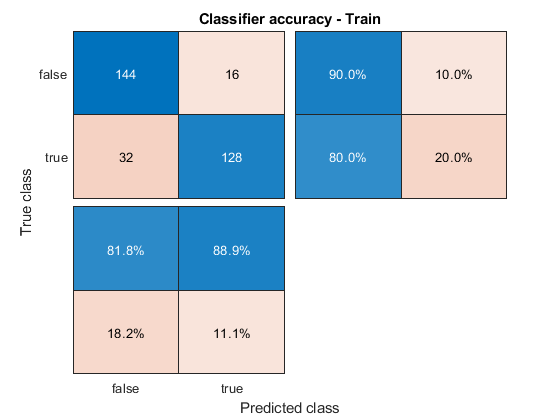

TrainCorrectRate = 0.8500

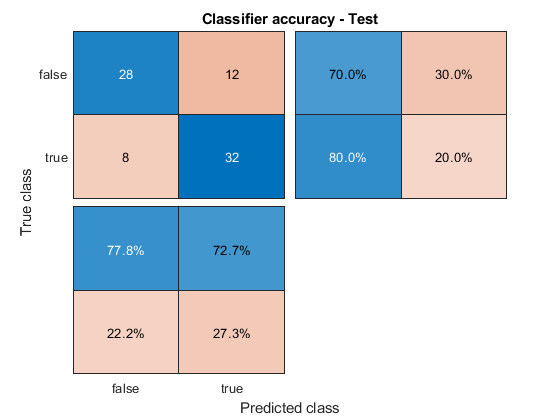

TestCorrectRate = 0.7500

% The function 'select' is found at the end of this script.
% It takes in the ground truth and randomly selects arg1 number of labels such that there are equal number of labels for each class
% If further breaks each class into a training and a test set according to the ratio provided as arg2
% The output are 2 lists of indices; one for training (containing equal number from all classes) and one for testing
[SelectedTrain_Idn1,SelectedTest_Idn1]=select(200,0.8,CompleteData_GrndTrth.Class);

% Using the indices to extract the training data and ground truth from CompleteData1
TrainData_Raw=CompleteData1(SelectedTrain_Idn1,3:end);
Train_GrndTrth=CompleteData_GrndTrth(SelectedTrain_Idn1,1).Class;
% Using the indices to extract the test data and ground truth from CompleteData1
TestData_Raw=CompleteData1(SelectedTest_Idn1,3:end);
Test_GrndTrth=CompleteData_GrndTrth(SelectedTest_Idn1,1).Class;

% Using the model_LDA function to train a linear discriminant classifier
% Model_LDA will also test the model using the test dataset and test ground truth
% The output are the model accuracies for the training and test datasets respectively
[~,TrainAccuracy,TestAccuracy]=model_LDA(TrainData_Raw,Train_GrndTrth,TestData_Raw,Test_GrndTrth);

## PCA-LDA

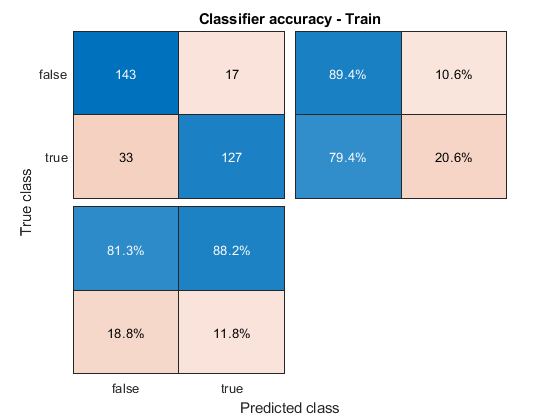

TrainCorrectRate = 0.8438

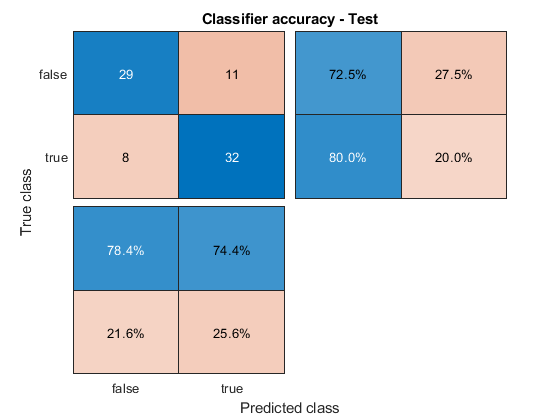

TestCorrectRate = 0.7625

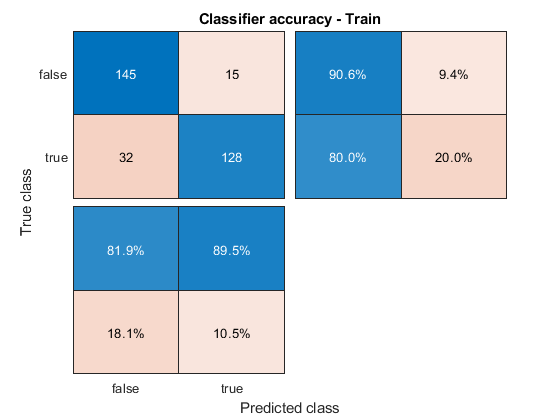

TrainCorrectRate = 0.8531

TestCorrectRate = 0.7500

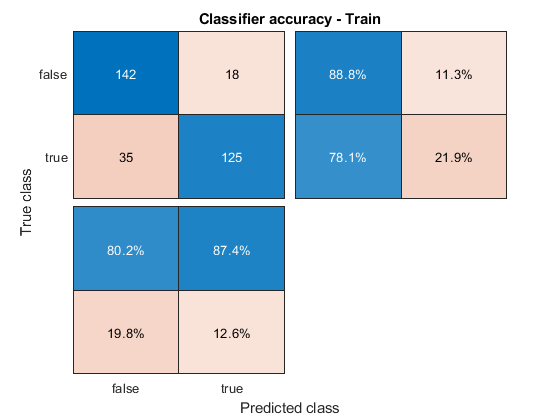

TrainCorrectRate = 0.8344

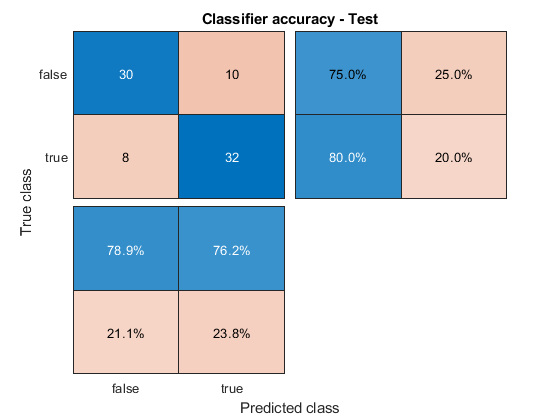

TestCorrectRate = 0.7750

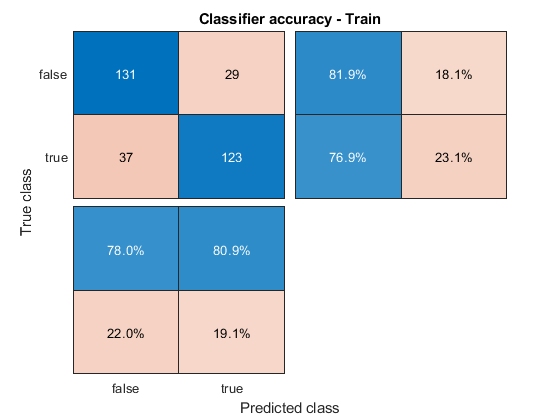

TrainCorrectRate = 0.7938

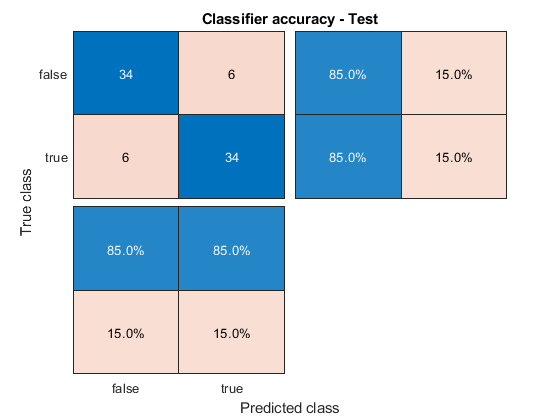

TestCorrectRate = 0.8500

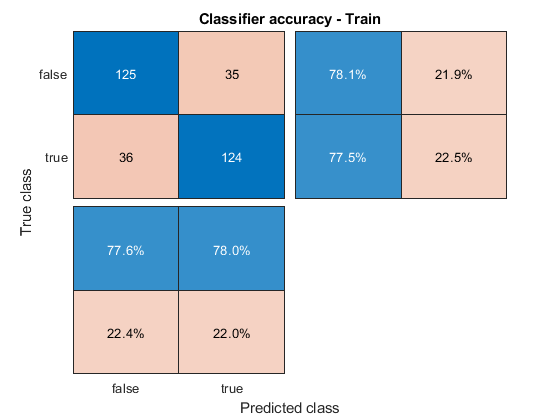

TrainCorrectRate = 0.7781

TestCorrectRate = 0.8500

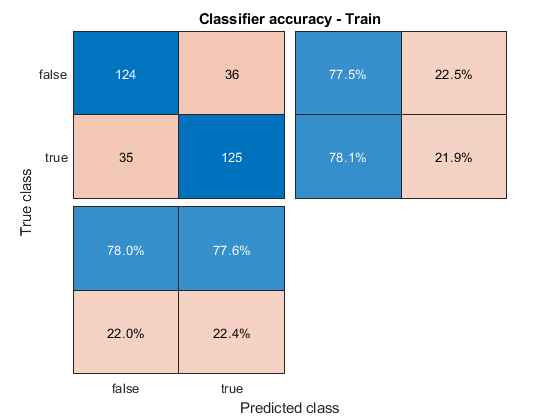

TrainCorrectRate = 0.7781

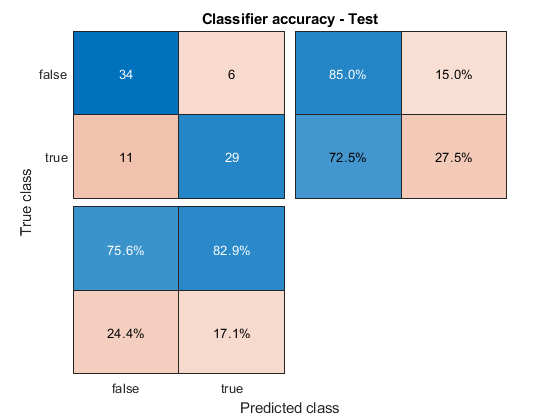

TestCorrectRate = 0.7875

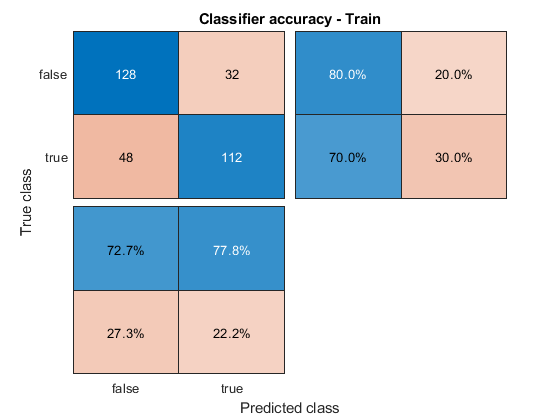

TrainCorrectRate = 0.7500

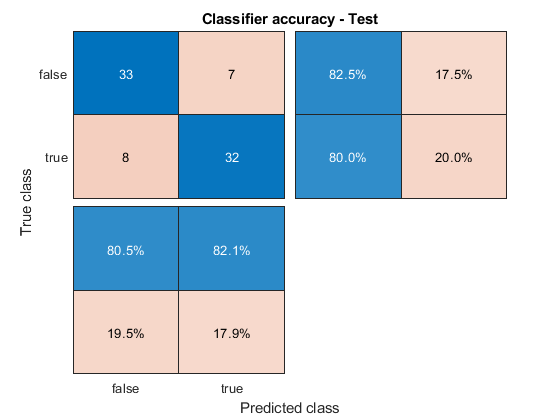

TestCorrectRate = 0.8125

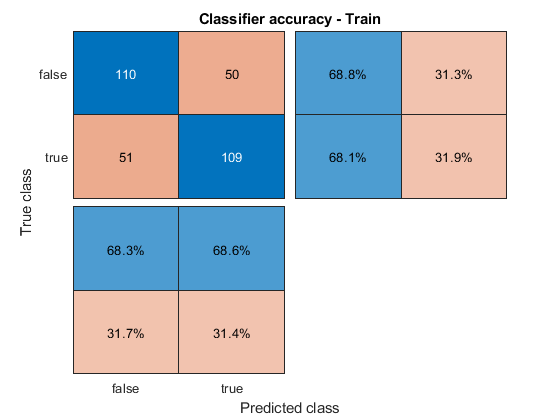

TrainCorrectRate = 0.6844

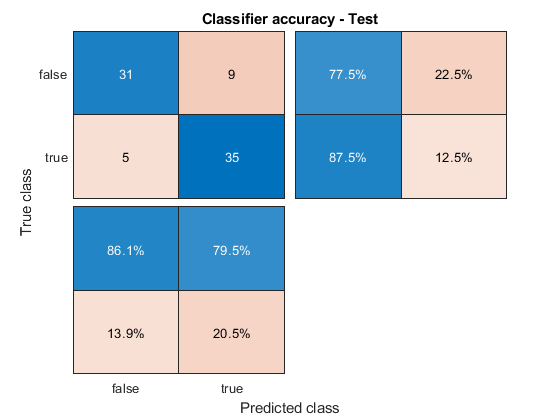

TestCorrectRate = 0.8250

% Builing an LDA model using the principle components of the raw data
mean_TrainData=mean(TrainData_Raw{:,:},'omitNaN');
SD_TrainData=std(TrainData_Raw{:,:},'omitNaN');
standardized_TrainData=(TrainData_Raw{:,:}-mean_TrainData)./SD_TrainData; % 0 centering the data and standardizing the SD to 1
[PCA_coeff,PCA_score,PCA_latent] = pca(standardized_TrainData); % Getting the Principal components
standardized_TestData=(TestData_Raw{:,:}-mean_TrainData)./SD_TrainData; % Standardising the test data using the mean and SD of the training set
Test_PCA_projections=standardized_TestData*PCA_coeff; % Projecting the test data on the principal components of the training set. The training and test sets have to be processed identically for the model to work,

PCs2use=[40,35,30,25,20,15,10,5];  % number of principal components to use for training and testing the model
ModelLDA_Accuracy=table(0,TrainAccuracy,TestAccuracy,'VariableNames',{'Num_of_PCs','Train_Accuracy','Test_Accuracy'});
for PC_count=1:numel(PCs2use)
    % Training and testing the model with each of the values specified in PCs2use
    % Saving the training and test accuracies in each case
    [~,TrainAccuracy,TestAccuracy]=model_LDA(PCA_score(:,1:PCs2use(PC_count)),Train_GrndTrth,Test_PCA_projections(:,1:PCs2use(PC_count)),Test_GrndTrth);
    ModelLDA_Accuracy(end+1,1:3)={PCs2use(PC_count),TrainAccuracy,TestAccuracy};
end

ModelLDA_Accuracy = 9×3 table
    Num_of_PCs    Train_Accuracy    Test_Accuracy
    __________    ______________    _____________

         0              0.85             0.75    
        40           0.84375           0.7625    
        35           0.85313             0.75    
        30           0.83437            0.775    
        25           0.79375             0.85    
        20           0.77812             0.85    
        15           0.77812           0.7875    
        10              0.75           0.8125    
         5           0.68437            0.825    


NumOfPCsChoosen = 25

TrainCorrectRate = 0.7938

TestCorrectRate = 0.8500

a =   ClassificationDiscriminant
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 320
              DiscrimType: 'linear'
                       Mu: [2×25 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


a_TrnA = 0.7938

a_TstA = 0.8500

ModelLDA_Accuracy % Displays a table containing the number of pricipal components used, the training accuracy and the test accuracy for all the trials

## Visualizing the model

## Variance explained by PCA

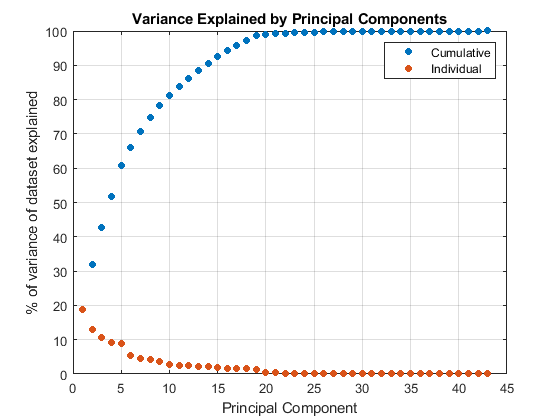


% Plot the total variance explained by each individual principal component along with the cumulative total that has been explained.
figure
plot([cumsum(PCA_latent(1:size(PCA_latent,1)))/sum(PCA_latent) PCA_latent(1:size(PCA_latent,1))/sum(PCA_latent)]*100,'.',...
    'MarkerSize',18)
xlabel('Principal Component');
ylabel('% of variance of dataset explained');
legend('Cumulative','Individual')
title('Variance Explained by Principal Components')
grid on

## PCA plots

% Defining the Principal Components of interest
PC_p1=22

PC_p1 = 22

PC_p2=25

PC_p2 = 25

PC_p3=21

PC_p3 = 21

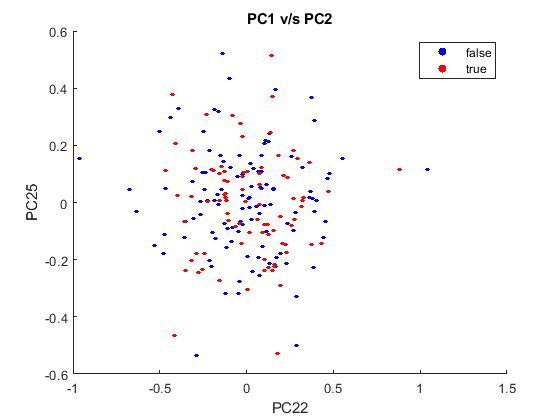


% visualize two principal components
Plot_Colors=['b';'r';'k';'m';'c'];
Categories=unique(categorical(CompleteData_GrndTrth.Class));
figure
hold on
for category_count=1:size(Categories,1)
    X_values=PCA_score(categorical(Train_GrndTrth)==Categories(category_count),PC_p1);
    Y_values=PCA_score(categorical(Train_GrndTrth)==Categories(category_count),PC_p2);
    scatter(X_values,Y_values,10,Plot_Colors(category_count,:),'filled','MarkerFaceAlpha',1)
end
hold off
title (['PC1 v/s PC2'])
xlabel('PC22')
ylabel('PC25')
legend (cellstr(Categories),'Interpreter','none')

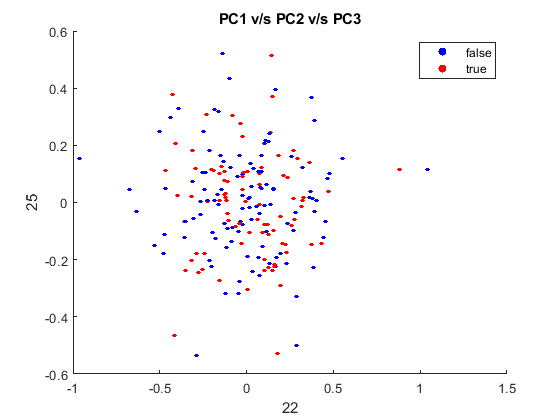



% visualize three principal components
% Plot_Colors=['b';'g';'r';'k';'m';'c'];
figure
hold on
for category_count=1:size(Categories,1)
    X_values=PCA_score(categorical(Train_GrndTrth)==Categories(category_count),PC_p1);
    Y_values=PCA_score(categorical(Train_GrndTrth)==Categories(category_count),PC_p2);
    Z_values=PCA_score(categorical(Train_GrndTrth)==Categories(category_count),PC_p3);
    scatter3(X_values,Y_values,Z_values,10,Plot_Colors(category_count,:),'filled','MarkerFaceAlpha',1)
end
hold off
title (['PC1 v/s PC2 v/s PC3'])
xlabel(num2str(PC_p1))
ylabel(num2str(PC_p2))
zlabel(num2str(PC_p3))
legend (cellstr(Categories),'Interpreter','none')

## Loading coefficient on PCp

% bar_colors=[0.4940 0.1840 0.75;0 0 0;1 0 1];
param_groups=[1,ones(1,7)*2,ones(1,7)*3,ones(1,7)*4,ones(1,7)*5,ones(1,7)*6,ones(1,7)*7];
bar_colors=jet(numel(unique(param_groups)));

PC_p=PC_p1

PC_p = 22

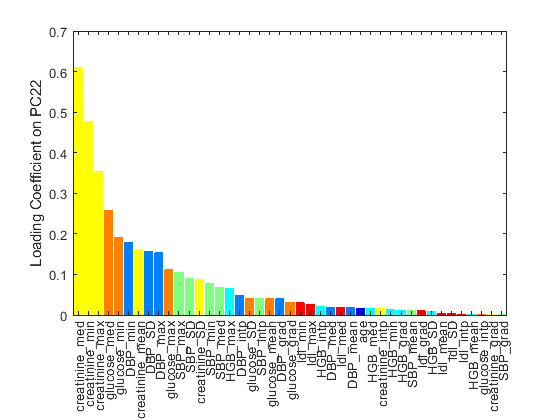

LoadCoeff_on_p=abs(PCA_coeff(:,PC_p));
[~,coeff_sorting_idx]=sort(LoadCoeff_on_p,'descend');
PCp_param_names=TrainData_Raw.Properties.VariableNames(coeff_sorting_idx);
PCp_sorted_param_names=reordercats(categorical(PCp_param_names),PCp_param_names);
sorted_LoadCoeff_on_p=LoadCoeff_on_p(coeff_sorting_idx);
figure
bar(PCp_sorted_param_names,sorted_LoadCoeff_on_p,'FaceColor','flat','EdgeColor','flat','CData',bar_colors(param_groups(coeff_sorting_idx),:))
ylabel(['Loading Coefficient on PC',num2str(PC_p)])
set(gca,'TickLabelInterpreter', 'none')


PC_p=PC_p2

PC_p = 25

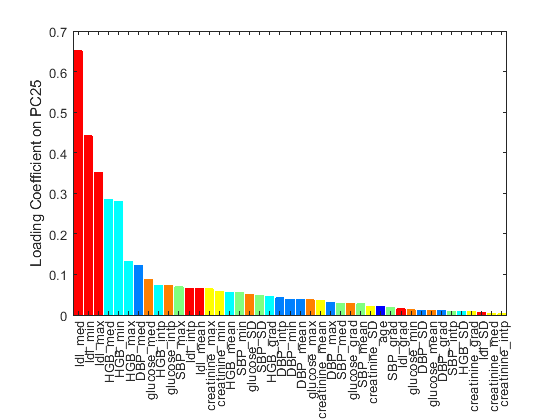

LoadCoeff_on_p=abs(PCA_coeff(:,PC_p));
[~,coeff_sorting_idx]=sort(LoadCoeff_on_p,'descend');
PCp_param_names=TrainData_Raw.Properties.VariableNames(coeff_sorting_idx);
PCp_sorted_param_names=reordercats(categorical(PCp_param_names),PCp_param_names);
sorted_LoadCoeff_on_p=LoadCoeff_on_p(coeff_sorting_idx);
figure
bar(PCp_sorted_param_names,sorted_LoadCoeff_on_p,'FaceColor','flat','EdgeColor','flat','CData',bar_colors(param_groups(coeff_sorting_idx),:))
ylabel(['Loading Coefficient on PC',num2str(PC_p)])
set(gca,'TickLabelInterpreter', 'none')


PC_p=PC_p3

PC_p = 21

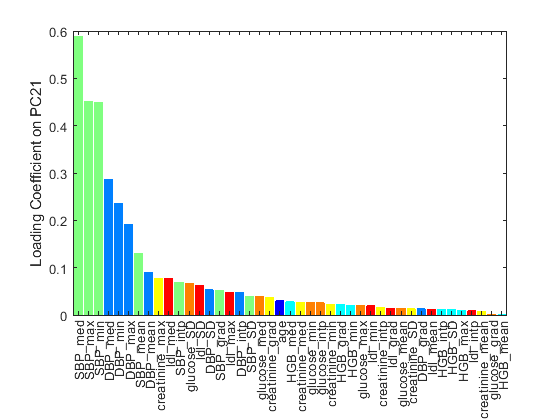

LoadCoeff_on_p=abs(PCA_coeff(:,PC_p));
[~,coeff_sorting_idx]=sort(LoadCoeff_on_p,'descend');
PCp_param_names=TrainData_Raw.Properties.VariableNames(coeff_sorting_idx);
PCp_sorted_param_names=reordercats(categorical(PCp_param_names),PCp_param_names);
sorted_LoadCoeff_on_p=LoadCoeff_on_p(coeff_sorting_idx);
figure
bar(PCp_sorted_param_names,sorted_LoadCoeff_on_p,'FaceColor','flat','EdgeColor','flat','CData',bar_colors(param_groups(coeff_sorting_idx),:))
ylabel(['Loading Coefficient on PC',num2str(PC_p)])
set(gca,'TickLabelInterpreter', 'none')

## Weight of each type of parameter

NumOfPCsChoosen=25  % Defining the model we want to analyse. Here we've chosen the model with 25 principal components
[ModelOfInterest]=model_LDA(PCA_score(:,1:NumOfPCsChoosen),Train_GrndTrth,Test_PCA_projections(:,1:NumOfPCsChoosen),Test_GrndTrth) % Recreating that model and saving it to the workspace for inspection
% The weight of each parameter is found in 'coeff' field of the model 'ModelOfInterest'

## Processing meds data

Meds=unique(categorical(RawData.meds.drug));  % Obtaining the number of different drugs being considered
Meds_ParamNames=cell(1,6*numel(Meds));  % 6 parameters will be extracted from the timeseries data of each drug for each patient
Meds_Params=zeros(length(id),size(Meds_ParamNames,2));
% Defining the names of the parameters extracted from the drug data
for MedsField_count=1:numel(Meds)
    Meds_ParamNames{(MedsField_count*6)-5}=[char(Meds(MedsField_count)),'_DurationRange'];
    Meds_ParamNames{(MedsField_count*6)-4}=[char(Meds(MedsField_count)),'_DurationMidpt'];
    Meds_ParamNames{(MedsField_count*6)-3}=[char(Meds(MedsField_count)),'_TotDuration'];
    Meds_ParamNames{(MedsField_count*6)-2}=[char(Meds(MedsField_count)),'_AvgDailyDose'];
    Meds_ParamNames{(MedsField_count*6)-1}=[char(Meds(MedsField_count)),'_SDDailyDose'];
    Meds_ParamNames{(MedsField_count*6)}=[char(Meds(MedsField_count)),'_DoseGrad'];
    
    % Analysis is performed one drug at a time
    % Can be parallelized
    MedsShortlistIdx=categorical(RawData.meds.drug)==Meds(MedsField_count);
    % Obtaining all the fields for drug defined in MedsShortlistIdx
    Shortlisted_Dataset=RawData.meds(MedsShortlistIdx,:);
    RelevantID=unique(Shortlisted_Dataset.id);
    % Processing for one ID at a time
    % Can be parallelized
    for id_count=1:numel(RelevantID)
        SingleID_Shortlisted_Dataset=Shortlisted_Dataset(Shortlisted_Dataset.id==RelevantID(id_count),:);
        % Extracting features from the drug data
        DurationRange=max(SingleID_Shortlisted_Dataset{:,5})-min(SingleID_Shortlisted_Dataset{:,4})+1;
        TotDuration=sum((SingleID_Shortlisted_Dataset{:,5}-SingleID_Shortlisted_Dataset{:,4})+1);
        AvgDailyDose=sum(TotDuration.*SingleID_Shortlisted_Dataset{:,3})/TotDuration;
        x=[];
        y=[];
        for instance_count=1:size(SingleID_Shortlisted_Dataset,1)
            Instance_Duration=SingleID_Shortlisted_Dataset{instance_count,4}:SingleID_Shortlisted_Dataset{instance_count,4};
            x=horzcat(x,Instance_Duration);
            y=horzcat(y,ones(1,numel(Instance_Duration))*SingleID_Shortlisted_Dataset{instance_count,3});
        end
        x=x';
        y=y';
        
        % Saving the feature extracted in a consistent format
        Meds_Params(RelevantID(id_count)+1,(MedsField_count*6)-5)=DurationRange;
        Meds_Params(RelevantID(id_count)+1,(MedsField_count*6)-4)=median(x);
        Meds_Params(RelevantID(id_count)+1,(MedsField_count*6)-3)=TotDuration;
        Meds_Params(RelevantID(id_count)+1,(MedsField_count*6)-2)=AvgDailyDose;
        Meds_Params(RelevantID(id_count)+1,(MedsField_count*6)-1)=std(y);
        if length(x)>1
            % If a patient has consumed a particular drug, a first order polynomial is fitted to the data and its gradient is extracted
            % This is a measure of the trend in consumption of that drug by that patient
            f = fit(x,y,'poly1');
            Meds_Params(RelevantID(id_count)+1,(MedsField_count*6))=f.p1;
        end
    end
end


% Concatenating the new drug freatures to the features extracted previously
CompleteData2=[CompleteData1,array2table(Meds_Params,'VariableNames',Meds_ParamNames)];


## Parameters for logistic regression and neural network

% Preprocessing the data for training a logistic regression and a neura network
TrainData2_Raw=CompleteData2(SelectedTrain_Idn1,:); % Obtaining the data for the labels to be used for trainig
Train_GrndTrth=CompleteData_GrndTrth(SelectedTrain_Idn1,1).Class;
TestData2_Raw=CompleteData2(SelectedTest_Idn1,:); % Obtaining the data for the labels to be used for testing
Test_GrndTrth=CompleteData_GrndTrth(SelectedTest_Idn1,1).Class;

% % Converting categorical data to numeric
% TrainData2_Raw.race=grp2idx(TrainData2_Raw.race);
% TrainData2_Raw.gender=grp2idx(TrainData2_Raw.gender);
% TestData2_Raw.race=grp2idx(TestData2_Raw.race);
% TestData2_Raw.gender=grp2idx(TestData2_Raw.gender);

Regress_Test_GrndTrth=Test_GrndTrth;
Regress_Train_GrndTrth=Train_GrndTrth;
Regress_TrainData=zeros(size(Regress_Train_GrndTrth,1),7);
Regress_TestData=zeros(size(Regress_Test_GrndTrth,1),7);
% Converting categorical data into binary format with the information saved as the index of the matrix
% May not be necessary. Have to try with and without
for count=1:size(Regress_Train_GrndTrth,1)
    Regress_TrainData(count,TrainData2_Raw{count,1})=1;
end
for count=1:size(Regress_Train_GrndTrth,1)
    Regress_TrainData(count,TrainData2_Raw{count,2}+5)=1;
end
Regress_TrainData=[Regress_TrainData,TrainData2_Raw{:,3:end}];
for count=1:size(Regress_Test_GrndTrth,1)
    Regress_TestData(count,TestData2_Raw{count,1})=1;
end
for count=1:size(Regress_Test_GrndTrth,1)
    Regress_TestData(count,TestData2_Raw{count,2}+5)=1;
end
Regress_TestData=[Regress_TestData,TestData2_Raw{:,3:end}];


## Running the Logistic Regression


Lambda=[0,100,150,200,250,300]  % Regularization values to try

Lambda =      0   100   150   200   250   300


% RegressClassi will take in the train data, test data and regularization parameters and make a model for each regularization parameter submitted
% The output are the model predictions on the training and test data for each regularization parameter
[Reg_TrainPredictions,Reg_TestPredictions]=RegressClassi(Regress_TrainData,Regress_TestData,Lambda,Train_GrndTrth,Test_GrndTrth);


Local minimum possible.

fminunc stopped because the size of the current step is less than
the selected value of the step size tolerance.

<stopping criteria details>


Local minimum possible.

fminunc stopped because the 

## Accuracy of Logistic Regression

## Train Accuracy

% Initializing parameter. They will have the same size as the number of regularization parameters tried (number of columns predicted)
TrainAccuracy_Regress=zeros(size(Reg_TrainPredictions,2),1);
TestAccuracy_Regress=zeros(size(Reg_TrainPredictions,2),1);


for trial_count=1:size(Reg_TrainPredictions,2)
    % Creating confusion matrices for each set of training data predictions
    figure
    ConfusionMatrix = confusionchart(Train_GrndTrth,logical(Reg_TrainPredictions(:,trial_count)));
    ConfusionMatrix.ColumnSummary = 'column-normalized';
    ConfusionMatrix.RowSummary = 'row-normalized';
    ConfusionMatrix.Title = 'Classifier accuracy - Train';
    cp = classperf(Train_GrndTrth,logical(Reg_TrainPredictions(:,trial_count))); % evaluating class performance
    TrainAccuracy_Regress(trial_count,1)=cp.CorrectRate; % saving the class performance for each regularization parameter used

## Test Accuracy

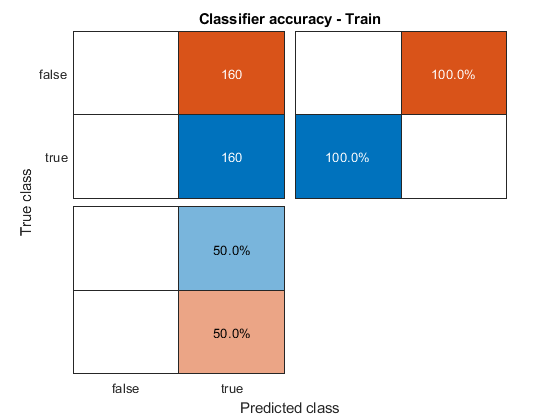

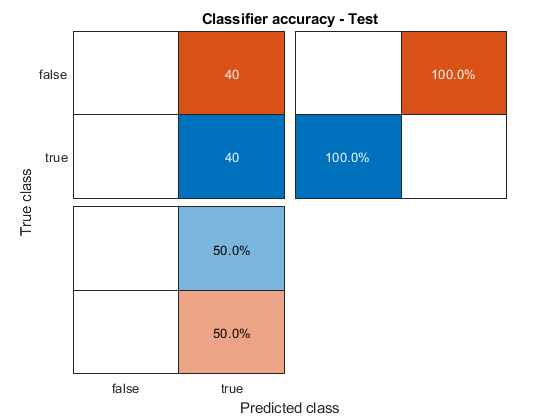

    % Creating confusion matrices for each set of test data predictions
    figure
    ConfusionMatrix = confusionchart(Test_GrndTrth,logical(Reg_TestPredictions(:,trial_count)));
    ConfusionMatrix.ColumnSummary = 'column-normalized';
    ConfusionMatrix.RowSummary = 'row-normalized';
    ConfusionMatrix.Title = 'Classifier accuracy - Test';
    cp = classperf(Test_GrndTrth,logical(Reg_TestPredictions(:,trial_count))); % evaluating class performance
    TestAccuracy_Regress(trial_count,1)=cp.CorrectRate; % saving the class performance for each regularization parameter used
    
end


% Building a table containing all the training aand test accuracies for each regularization parameter used
ModelRegress_Accuracy=table(Lambda',TrainAccuracy_Regress,TestAccuracy_Regress,'VariableNames',{'Lambda','Train_Accuracy','Test_Accuracy'})

ModelRegress_Accuracy = 6×3 table
    Lambda    Train_Accuracy    Test_Accuracy
    ______    ______________    _____________

       0           0.5               0.5     
     100           0.5               0.5     
     150           0.5               0.5     
     200           0.5               0.5     
     250           0.5               0.5     
     300           0.5               0.5     


## Calling Neural Network

ModelNeuNet_Accuracy=[];

lambda=[10,25,50];  % Defining the regularization parameters to be tried for the neural network
UnitsInHiddenL=[10,50,100,150]; % Defining the number of units to be tried in the hidden layer of the neural network
MaxIterate=500; % maximum number of iterations before trigering the stop condition

% Looping through all the options to be tried
% Can be parallelized
for lambda_count=1:numel(lambda)
    for neuron_count=1:numel(UnitsInHiddenL)
        for MaxIterate_count=1:numel(MaxIterate)
            % Outputs the model predictions for the training data and test data together with the accuracies for every possible combination of parameters set
            [NeuNet_TrainPredictions,NeuNet_TestPredictions,Tr_Accuracy,Te_Accuracy]=...
                NeuNet(Regress_TrainData,Regress_Train_GrndTrth,Regress_TestData,Regress_Test_GrndTrth,...
                UnitsInHiddenL(neuron_count),lambda(lambda_count),MaxIterate(MaxIterate_count));
            % saving the results in a table
            ModelNeuNet_Accuracy=[ModelNeuNet_Accuracy;table(UnitsInHiddenL(neuron_count),lambda(lambda_count),MaxIterate(MaxIterate_count),Tr_Accuracy,Te_Accuracy,'VariableNames',{'Units_in_Hidden_Layer','Lambda','MaxIter','Train_Accuracy','Test_Accuracy'})];
        end
    end
end

Iteration     1 | Cost: 1.486366e+00
Iteration     2 | Cost: 1.442318e+00
Iteration     3 | Cost: 1.429975e+00
Iteration     4 | Cost: 1.398535e+00
Iteration     5 | Cost: 1.398140e+00
Iteration     6 | Cost: 1.396569e+00
Iteration     7 | Cost: 1.394277e+00
Iteration     8 | Cost: 1.389813e+00
Iteration     9 | Cost: 1.385107e+00
Iteration    10 | Cost: 1.380024e+00
Iteration    11 | Cost: 1.375837e+00
Iteration    12 | Cost: 1.373027e+00
Iteration    13 | Cost: 1.370208e+00
Iteration    14 | Cost: 1.365470e+00
Iteration    15 | Cost: 1.365240e+00
Iteration    16 | Cost: 1.365046e+00
Iteration    17 | Cost: 1.357943e+00
Iteration    18 | Cost: 1.349616e+00
Iteration    19 | Cost: 1.346951e+00
Iteration    20 | Cost: 1.343285e+00
Iteration    21 | Cost: 1.341104e+00
Iteration    22 | Cost: 1.338348e+00
Iteration    23 | Cost: 1.336516e+00
Iteration    24 | Cost: 1.334078e+00
Iteration    25 | Cost: 1.333791e+00
Iteration    26 | Cost: 1.330850e+00
Iteration    27 | Cost: 1.327991e+00
I


ModelNeuNet_Accuracy % Displays the table

ModelNeuNet_Accuracy = 52×5 table
    Units_in_Hidden_Layer    Lambda    MaxIter    Train_Accuracy    Test_Accuracy
    _____________________    ______    _______    ______________    _____________

              10                0        500          74.688               55    
              50                0        500          85.313             42.5    
             100                0        500          86.875            53.75    
             150                0        500          94.063            56.25    
              10              0.5        500          75.938               55    
              50              0.5        500          85.938            53.75    
             100              0.5        500              90             62.5    
             150              0.5        500          92.

# In-built Function

## Random sampling of input data

function [TrainSelectionIdn,TestSelectionIdn]=select(ClassSelectionSizes,TrainFraction,ClassField)
% This function takes in the ground truth and randomly selects arg1 number of labels such that there are equal number of labels for each class
% If further breaks each class into a training and a test set according to the ratio provided as arg2
% The output are 2 lists of indices; one for training (containing equal number from all classes) and one for testing
TrainSelectionSizes=round(ClassSelectionSizes*TrainFraction);
TestSelectionSizes=ClassSelectionSizes-TrainSelectionSizes;
Classes=unique(categorical(ClassField)); % Identifying the classes that exist in the dataset
TrainSelectionIdn=zeros(numel(Classes)*TrainSelectionSizes,1);
TestSelectionIdn=zeros(numel(Classes)*TestSelectionSizes,1);
for Class_count=1:numel(Classes)
    Class_Idn=find(categorical(ClassField)==Classes(Class_count)); % identifying the indices containing the data from a particular class
    % Ramdom sampling of the indices to shortlist some for the trainig set
    TrainSample=datasample(Class_Idn,TrainSelectionSizes,'Replace',true); % can be switched to off only if not oversampling
    TrainSelectionIdn(((Class_count-1)*TrainSelectionSizes)+1:((Class_count-1)*TrainSelectionSizes)+TrainSelectionSizes,1)=TrainSample;
    % Random selection from the remaining indices to be used for the test set
    TestSelectionIdn(((Class_count-1)*TestSelectionSizes)+1:((Class_count-1)*TestSelectionSizes)+TestSelectionSizes,1)=...
        datasample(setdiff(Class_Idn,TrainSample),TestSelectionSizes,'Replace',true); % can be switched to off only if not oversampling
end
end
